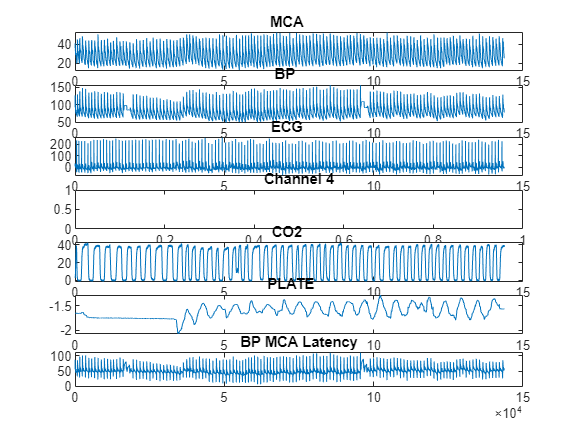

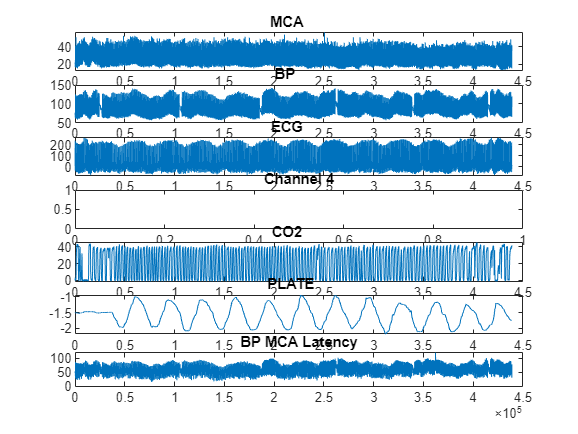

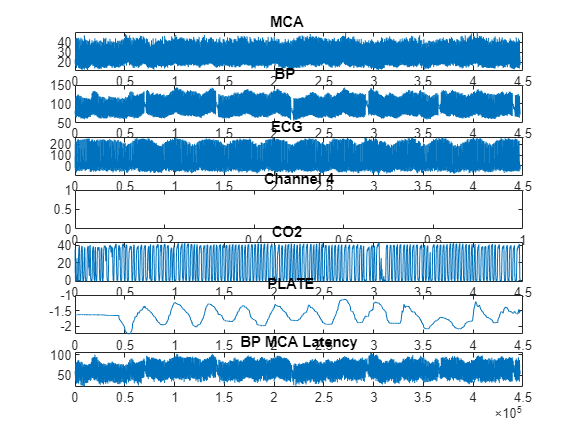

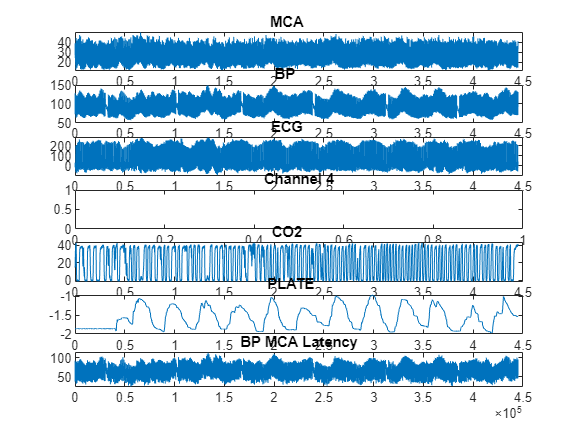

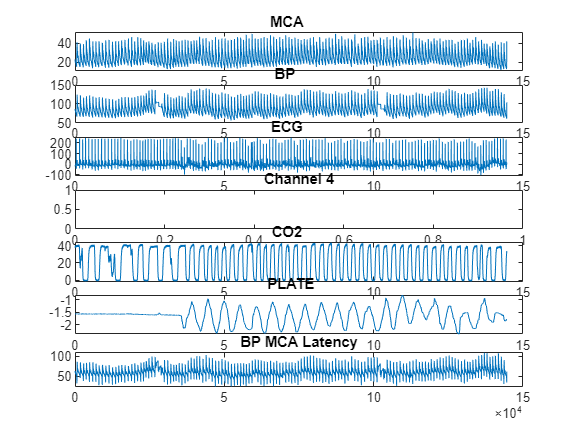

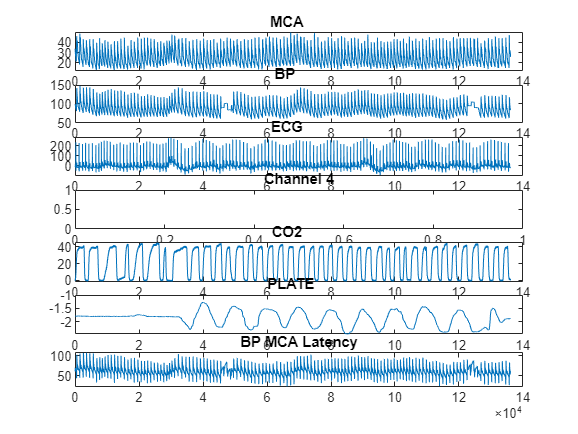

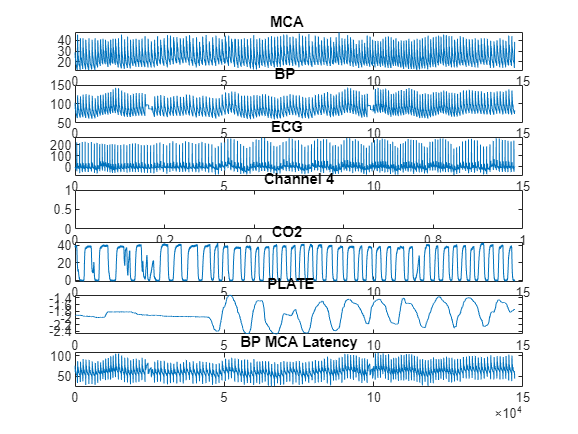

n = 7; % # of subplots in data block
m = 1; % data ranges in ticktimes
p = 1; % experiment plotting loop variable

data = data_block1;
tickblock = comtick_block1;
times = ticktimes_block1;

name = comtext_block1(namevar,1:14); % Experiment name in window
namevar = 2; % loop var

titles = titles_block1(i,1:9); % MCA, MP, ECG, etc.
titlevar = 1;

% 1001 ticks = 1 second

while p <= n % plots each test
    a = tickblock(m,1); % lower experiment data range
    b = tickblock(m+2,1); % upper experiment data range
    m = m + 3;
    figure("Name",name);

    for i = 1:n % plots each graph in test
        subplot(n,1,i);
        plot(data(i,a:b))
        title(titles_block1(titlevar,1:9))
        titlevar = titlevar + 1;
        i = i + 1;
    end
    
    %add any extra subplots here
    bpmca = data(2,a:b) - data(1,a:b);
    subplot(n+1,1,n+1);
    plot(bpmca)
    title("BP MCA Latency")
    
    
    
    titlevar = 1;
    p = p + 1;
    namevar = namevar + 3; %Updates each title
    name = comtext_block1(namevar,1:14); 
end